# Validate a Simulink Thermal Model

Run this script to compare simulation results of a Simulink® reduced-order thermal model (ROM) with the corresponding Motor-CAD™ transient calculations.

To regenerate the ROM, run the `GenerateSimulinkThermalModel.mlx`  (requires Motor-CAD v15 or higher).

Load the previously-generated ROM data:

load('data/OutputFromGSTM.mat');

## Validate an Induction Motor with Housing Water Jacket

modelName1 = 'e5_IM_HWJ_ROM';
open_system(modelName1);

Get ROM breakpoints from model workspace:

mdlWks = get_param(modelName1,'ModelWorkspace');
StateSpaceND = mdlWks.getVariable('StateSpaceND'); % array of state-space models
samplingGrid = StateSpaceND.SamplingGrid; % grid of breakpoints for shaft speed, coolant flow rate, and coolant inlet temperature
wBkpts = squeeze(samplingGrid.w(:,1,1))' %#ok<NASGU> % shaft speed breakpoints [rpm] 

wBkpts =          200        2000        4000        7000


frBkpts = squeeze(samplingGrid.fr1(1,:,1)) % housing water jacket flow rate breakpoints [lpm]

frBkpts =      3     6    10


TinBkpts = squeeze(samplingGrid.Tin1(1,1,:))' % housing water jacket inlet temperature breakpoints [degC]

TinBkpts =     20    60


### First Breakpoint

Compare the Simulink ROM model transient results with the Motor-CAD transient results with the first breakpoint values as inputs:

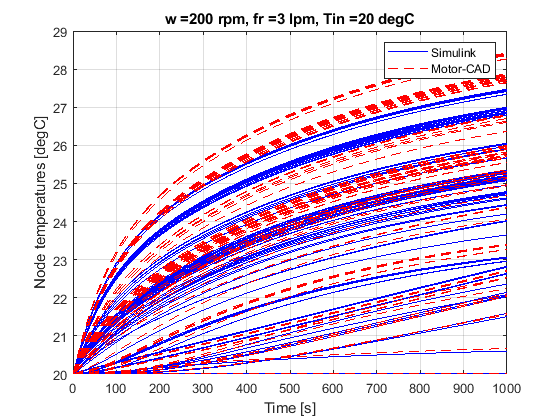

torqueVal = 30; % [N*m]
bkptIdxComb1 = [1,1,1];
e5maxTempError1 = compareSimulinkAndMcadAtBkpt(modelName1, motFile1, bkptIdxComb1, torqueVal);

### Last Breakpoint

Compare the Simulink ROM model transient results with the Motor-CAD transient results with the last breakpoint values as inputs:

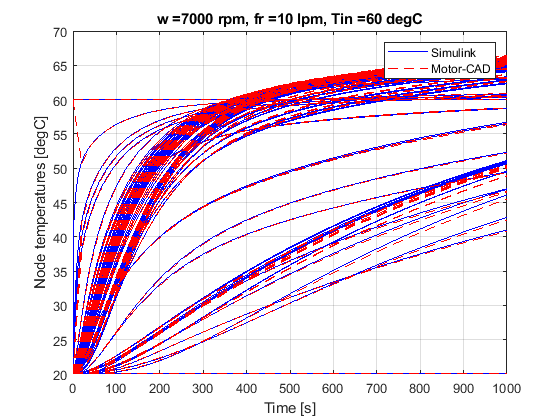

bkptIdxComb2 = [4,3,2];
e5maxTempError2 = compareSimulinkAndMcadAtBkpt(modelName1, motFile1, bkptIdxComb2, torqueVal);

### Error summary

Compare the maximum temperature error for each case:

e5error = table([bkptIdxComb1;bkptIdxComb2],[e5maxTempError1;e5maxTempError2], ...
    'VariableNames', ["BkptIdxComb", "MaxTempErrDegC"])

e5error = 2×2 table
    BkptIdxComb    MaxTempErrDegC
    ___________    ______________

    1    1    1       0.95493    
    4    3    2       0.88258    


## Validate a PMSM with Housing Water Jacket and Ventilated

modelName2 = 'e8_IPMSM_HWJandVent_ROM';
open_system(modelName2);

Get ROM breakpoints from model workspace:

mdlWks = get_param(modelName2,'ModelWorkspace');
StateSpaceND = mdlWks.getVariable('StateSpaceND'); % array of state-space models
samplingGrid = StateSpaceND.SamplingGrid; % grid of breakpoints for shaft speed, coolant flow rate, and coolant inlet temperature
wBkpts = squeeze(samplingGrid.w(:,1,1,1,1))' % shaft speed breakpoints [rpm]

wBkpts =          500        3000        7000


fr1Bkpts = squeeze(samplingGrid.fr1(1,:,1,1,1)) % housing water jacket flow rate breakpoints [lpm]

fr1Bkpts =      3    10


fr2Bkpts = squeeze(samplingGrid.fr2(1,1,:,1,1))' % ventilated flow rate breakpoints [lpm]

fr2Bkpts =      3    10


Tin1Bkpts = squeeze(samplingGrid.Tin1(1,1,1,:,1))' % housing water jacket inlet temperature breakpoints [degC]

Tin1Bkpts =     20    30    40


Tin2Bkpts = squeeze(samplingGrid.Tin2(1,1,1,1,:))' % ventilated inlet temperature breakpoints [degC]

Tin2Bkpts =     20    30    40


### First Breakpoint

Compare the Simulink ROM model transient results with the Motor-CAD transient results with the first breakpoint values as inputs:

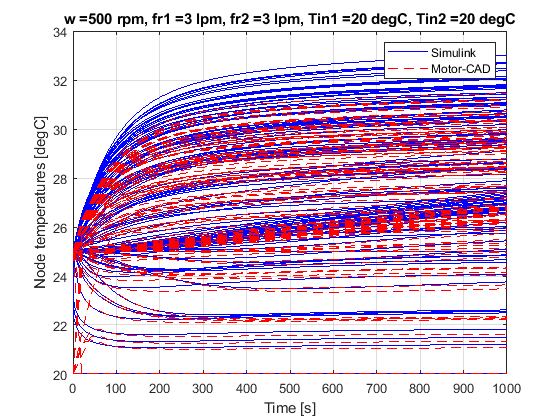

e8maxTempError1 = 1.5687

torqueVal = 70; % [N*m]
bkptIdxComb1 = [1,1,1,1,1];
e8maxTempError1 = compareSimulinkAndMcadAtBkpt(modelName2, motFile2, bkptIdxComb1, torqueVal)

### Last Breakpoint

Compare the Simulink ROM model transient results with the Motor-CAD transient results with the last breakpoint values as inputs:

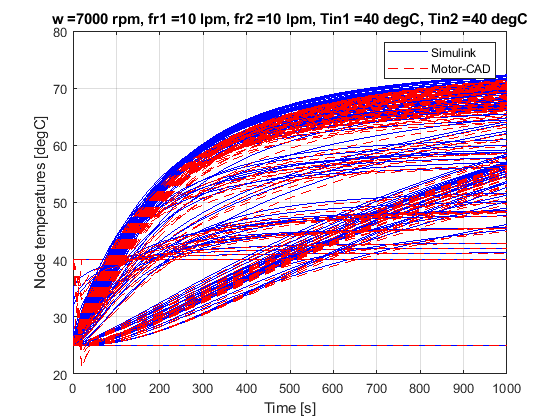

bkptIdxComb2 = [3,2,2,3,3];
e8maxTempError2 = compareSimulinkAndMcadAtBkpt(modelName2, motFile2, bkptIdxComb2, torqueVal);

### Error summary

Compare the maximum temperature error for each case:

e8error = table([bkptIdxComb1;bkptIdxComb2],[e8maxTempError1;e8maxTempError2], ...
    'VariableNames', ["BkptIdxComb", "MaxTempErrDegC"])

e8error = 2×2 table
         BkptIdxComb         MaxTempErrDegC
    _____________________    ______________

    1    1    1    1    1        1.5687    
    3    2    2    3    3        2.0012    


*Copyright 2022-2024 The MathWorks, Inc.*